# Robotics Lab 6

Syed Mustafa

Hazika Farooq

## Task 1 FSM

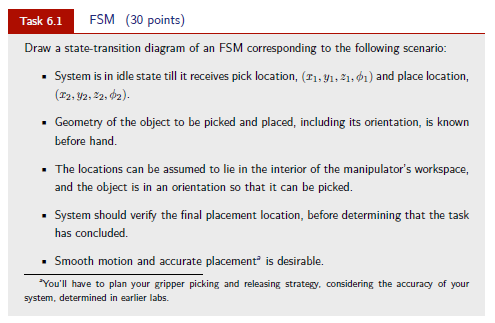

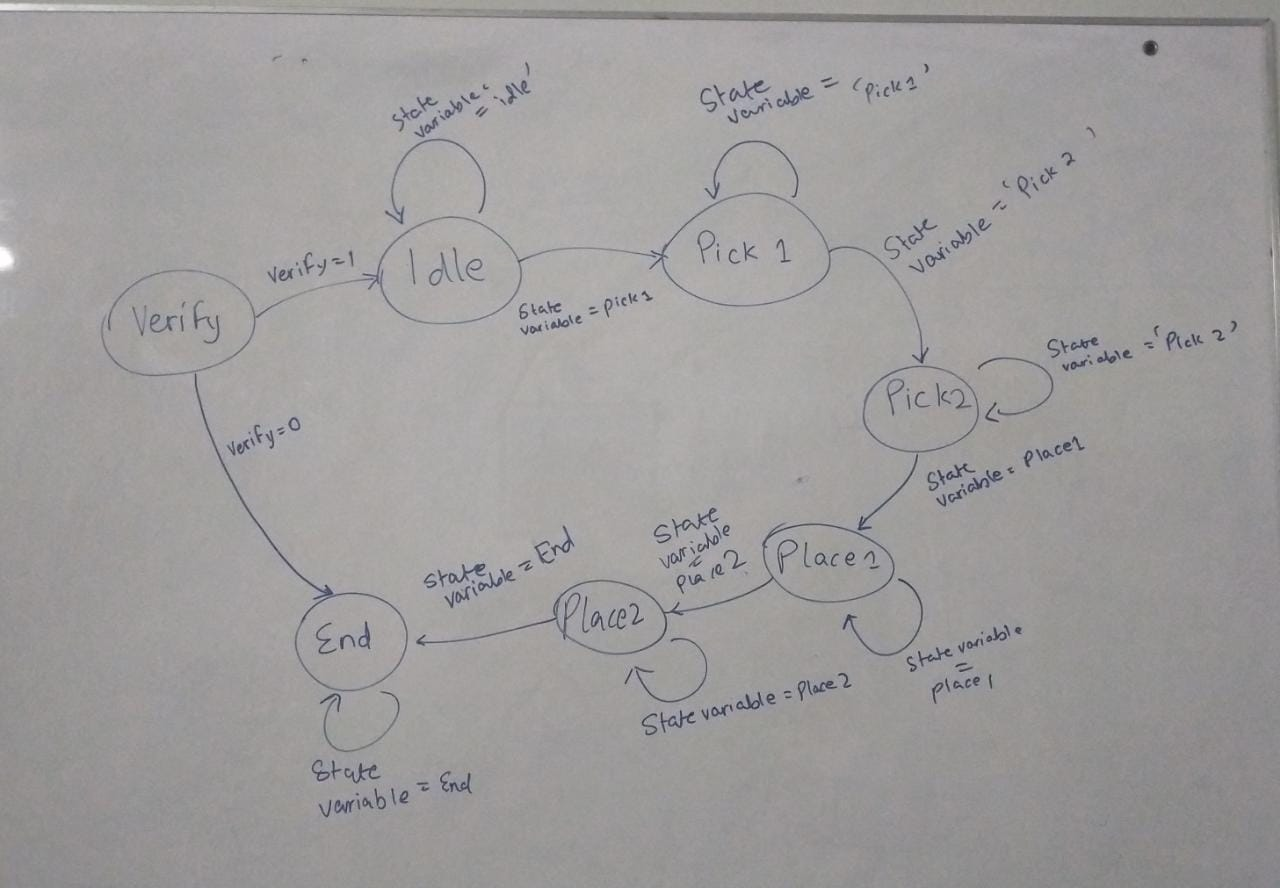

### Explaination of the states

- Verify

- Idle

- Pick 1

- Pick 2

- Place 1

- Place 2

- End

#### Verify

In this state the FSM will check if the place coordinates are valid. 

Note: An assumption here is that the workspace here is the area where |$\phi$| = 90. Thus with this constraint the reachable worspace becomes $r < a_2 + a_3 \ni  r
$ is the distance of the end effector from the origin {0} on $x_0-y_0$

#### Idle 

The joint coordinates are [0 0 0 0]

#### Pick 1 

The end effector is at z+5 pick coordinateas

#### Pick 2 

The end effector is at pick coordinates

The jaw is closed

#### Place 1 

The end effector is at z+5 place coordinateas

#### Place 2 

The end effector is at place coordinates

Th jaw is opened

#### End

The object has been placed and arm is back to idle position

## Task 2 FSM Implementation

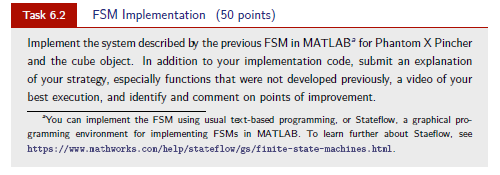

We have implemented a FSM in a function that would input the pick and place 

Pick = [16 -16 -1 -pi/2];
place = [-10 -16 -1 -pi/2];
FSM(Pick,place);

Note: The video link can be found in the comments of the submission

## Model Jacobian

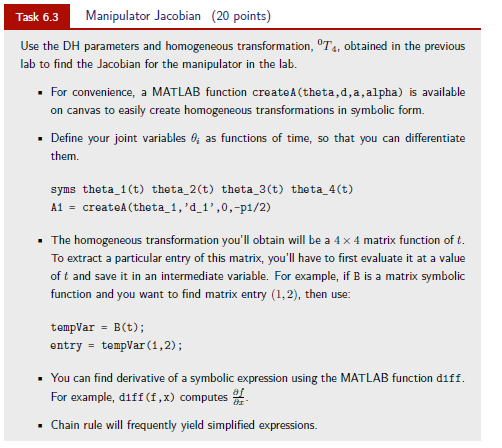

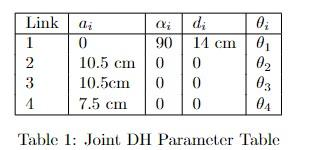


$$J=\left\lbrack \begin{array}{c}
J_v \\
J_w 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\textrm{Cross}\left({{\;}^0 z}_{i-1} ,\left({\;}^0 p_n -{\;}^0 p_{i-1} \right)\right)\\
{{\;}^0 z}_{i-1} 
\end{array}\right\rbrack$$


syms('theta_1(t)','theta_2(t)','theta_3(t)','theta_4(t)')
% createA(theta,d,a,alpha)
A1 = createA(theta_1, 14, 0, 90);
A2 = createA(theta_2,0, 10.5,0);
A3 = createA(theta_3, 0, 10.5, 0);

$$T1 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\left(t\right)\right) & -\sin\left(\theta_{1}\left(t\right)\right)\,\cos\left(90\right) & \sin\left(\theta_{1}\left(t\right)\right)\,\sin\left(90\right) & 0\\ \sin\left(\theta_{1}\left(t\right)\right) & \cos\left(\theta_{1}\left(t\right)\right)\,\cos\left(90\right) & -\cos\left(\theta_{1}\left(t\right)\right)\,\sin\left(90\right) & 0\\ 0 & \sin\left(90\right) & \cos\left(90\right) & 14\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A4 = createA(theta_4, 0, 7.5, 0);
T1 = A1;

$$T2 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\left(t\right)\right)\,\cos\left(\theta_{2}\left(t\right)\right)-\sin\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{2}\left(t\right)\right)\,\cos\left(90\right) & -\cos\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{2}\left(t\right)\right)-\cos\left(\theta_{2}\left(t\right)\right)\,\sin\left(\theta_{1}\left(t\right)\right)\,\cos\left(90\right) & \sin\left(\theta_{1}\left(t\right)\right)\,\sin\left(90\right) & \frac{21\,\cos\left(\theta_{1}\left(t\right)\right)\,\cos\left(\theta_{2}\left(t\right)\right)}{2}-\frac{21\,\sin\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{2}\left(t\right)\right)\,\cos\left(90\right)}{2}\\ \cos\left(\theta_{2}\left(t\right)\right)\,\sin\left(\theta_{1}\left(t\right)\right)+\cos\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{2}\left(t\right)\right)\,\cos\left(90\right) & \cos\left(\theta_{1}\left(t\right)\right)\,\cos\left(\theta_{2}\left(t\right)\right)\,\cos\left(90\right)-\sin\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{2}\left(t\right)\right) & -\cos\left(\theta_{1}\left(t\right)\right)\,\sin\left(90\right) & \frac{21\,\cos\left(\theta_{2}\left(t\right)\right)\,\sin\left(\theta_{1}\left(t\right)\right)}{2}+\frac{21\,\cos\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{2}\left(t\right)\right)\,\cos\left(90\right)}{2}\\ \sin\left(\theta_{2}\left(t\right)\right)\,\sin\left(90\right) & \cos\left(\theta_{2}\left(t\right)\right)\,\sin\left(90\right) & \cos\left(90\right) & \frac{21\,\sin\left(\theta_{2}\left(t\right)\right)\,\sin\left(90\right)}{2}+14\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T1 = T1(t)
T2 = A1*A2;

T2 = T2(t)
T3 = T2 * A3;

T3 = T3(t)
T4 = T3* A4;

$$J = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

T4 = T4(t)


J = sym(zeros(6, 4))
pn = T4(1:3, 4)

J(4:6, :) = [[0;0;1], T1(1:3,3), T2(1:3,3), T3(1:3,3)];

J(1:3,:) = [diff(T4(1:3,4), theta_1), diff(T4(1:3,4), theta_2), diff(T4(1:3,4), theta_3),diff(T4(1:3,4), theta_4)];

J1 = J(:,1)

J2 = J(:,2)
J3 = J(:,3)
J4 = J(:,4)